# **drawLoad**

Draw a distributed load

## Description

## Syntax

drawLoad(wd,h1,h2,type,x0,y0,ht,th)

drawSupport(__,LineSpec) 

p = drawSpring(__)

## Description

## Method

## Arguments

### Input Arguments

** wd      ** -- width or 0 if force

** h1,h2  ** -- height or

**Fx,Fy  **     if force

** nc        **-- number of interior vertical lines or ignored if force

** d          **-- disatnce from reference point

**  xr, yr  **-- reference point 

** rot       ** -- rotation of rectangle about reference point in degrees

### Optional Name-Value Pair Input Arguments

**'-ad',ad **- arowhead height

***LineSpec*** - specifies line properties, see [Line Properties](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.line-properties.html).

### Optional Output Arguments

**p **- structure with the fields

- p.x1,p.y1 -- lower left point

- p.x2,p.y2 - lower rigth point

- p.style - line style 

- p.width - line width 

- p.color - line color

## Examples

### Example 1

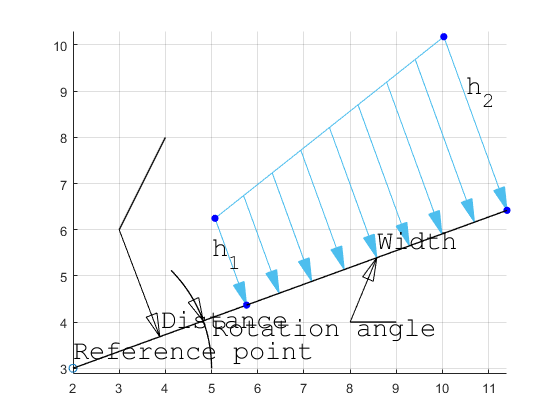

drawInit
gkInit
xr = 2;yr = 3;d = 4; n = 7; th = 20;
scatter(xr,yr)
gkText(xr,yr,'Reference point')
L=drawLine(xr,yr,'-rtheta',d,th);
L1=drawLeader(2,0.5,0.25,(L.xk(1)+L.xk(2))/2,(L.yk(1)+L.yk(2))/2,[3,4],[6,8]);
gkText(L1.xk(1),L1.yk(1),'Distance')
p = drawLoad(6,2,4,n,d,xr,yr,th,'-ad',0.5);
scatter(p.xk,p.yk,30,'b','filled')

L=drawLine(p.xk(1),p.yk(1),p.xk(2),p.yk(2));
L1=drawLeader(2,0.5,0.25,(L.xk(1)+L.xk(2))/2,(L.yk(1)+L.yk(2))/2,[8,9],[4,4]);
gkText(L1.xk(1),L1.yk(1),'Width')
drawCircle(xr,yr,3,0,th,'-np',40)
drawArcArrow(2,0.5,0.25,xr,yr,3,45,-45+th)
gkText(5,3.5,'Rotation angle')
gkText(5,5,'h_1')
gkText(10.5,8.5,'h_2')
grid on

%axis off
gkClose

### Example 2

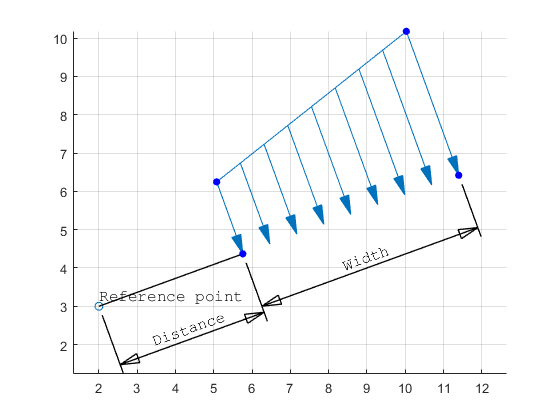

drawInit
xr = 2;yr = 3;d = 4; n = 7; th = 20;
scatter(xr,yr)
drawSet('FontSize',12)
drawText(xr,yr,'Reference point')
L=drawLine(xr,yr,'-rtheta',d,th);
drawDim(2,0.5,0.25,L.xk(1),L.yk(1),L.xk(2),L.yk(2),4,2,'-txt','Distance')
p = drawLoad(6,2,4,n,d,xr,yr,th,'-ad',0.5);
drawDim(2,0.5,0.25,p.xk(1),p.yk(1),p.xk(2),p.yk(2),9,4,'-txt','Width')
scatter(p.xk,p.yk,30,'b','filled')

grid on

%axis off

## **See Also**

## References